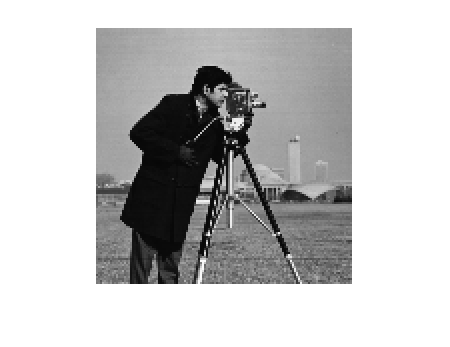

yemum = imread("/home/jacob/Documents/College/Sem5/DIP/LAB/cameraman.png");

yemum_256 = yemum(1:2:size(yemum,1), 1:2:size(yemum,2));
yemum_128 = yemum(1:4:size(yemum,1), 1:4:size(yemum,2));

A = [];

for i = 1:size(yemum_256, 1)
    for j = 1:size(yemum_256, 2)
        for k = 0:1
            for l = 0:1
                A(i*2 - k, j*2 - l) = yemum_256(i, j);
            end
        end
    end
end

resized = uint8(A);
% imshow(yemum_256)
imshow(resized)

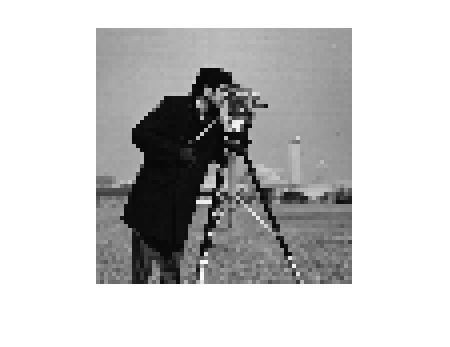


A = [];

for i = 1:size(yemum_128, 1)
    for j = 1:size(yemum_128, 2)
        for k = 0:3
            for l = 0:3
                A(i*4-k, j*4-l) = yemum_128(i, j);
            end
        end
    end
end

resized = uint8(A);
% imshow(yemum_128)
imshow(resized)